# Exercise 2:

In this task we will consider a stiff system with poles close to the imaginary axis, and second far from it (all poles in the LHP - Left Half-Plane). Based on the transfer funtion and the nyquist plot of the system we will try to determine its stability and regions of interest, as well as stability of the closed-loop system.

clear all
clc 

#### 1) Defining the transfer function

our system is defined by the following transfer function:

#### 2) Checking stability of the open-loop system

From the lectures we know that our system G(s)=N(s)/D(s) is stable iif all of the roots of the characteristic polynomial need to lie in the left-half plane (LHP) ie. 

all the zeros of the denominator have to be negative. Our poles are at s={-20, -0.001, -1} therefore the system is stable.

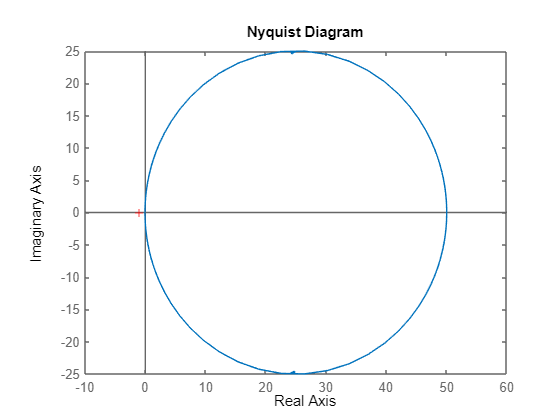

N=1;                        %numerator
D=[1 21.001 20.021 0.02];   %denumerator
sys=tf(N,D);                %transfer function

figure()
nyquist(sys)                %plotting nyquist plot

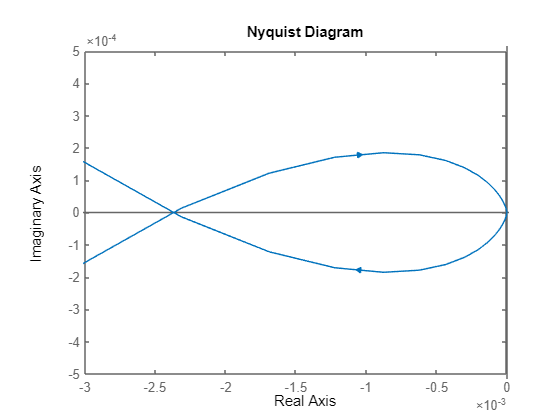

figure()
nyquist(sys)                            %plotting nyquist plot
axis([-0.003 0 -0.0005 0.0005])         %zooming in on the region of interest

#### 3) Checking close-loop system stability

We knew this region would be interesting, as stiff systems have some poles close to the origin of the coordinate frame, and we have to verify that there is no more than 1 pole on the imaginary axis, otherwise it is unstable.

Given the fact that the open-loop system is stable,and the Nyquist plot of the open-loop system presented above does not encircle the point (-1, j0) in the complex plane we can conclude that the closed-loop system is stable.